#  Chapter 6 - State Space Design of Control Systems 

##  Section 4 - Solving Pole-Placement Problems with Matlab

clear all; clc

**Notes: **

Pole-placement can be easily solved using the '*acker*' (for Ackermann) and '*place*' functions in MATLAB. Both will solve for the feedback gain matrix, K. The 'acker; function is used for single input systems only. 

For multiple input systems, different techniques must be used. One technique is to maximize the stability margin, also known as *Robust pole placement*. The 'place' Matlab command can be used for this technique. To apply this function, there must not be multiple poles in the set of desired closed-loop poles. Place can also be used for single input systems. 

## 6-4 Determine the Feedback Gain Matrix using 'acker' and 'place' functions

Consider the system from the previous chapter...using state feedback control $u=−Kx$, we desire to have the closed loop poles at $s=\text{ }\mu_i \text{ }\left(i=1,2,3\right)$, where $\mu_1 =−2+j4$, $\mu_2 =−2−j4$, and $\mu_3 =−10\ldotp \text{ }$Determine the state feedback gain matrix, K. 

% Using Ackermann's Method
A = [0 1 0; 0 0 1; -1 -5 -6];
B = [0; 0; 1];
J = [-2+j*4 -2-j*4 -10];    %define poles
K_acker = acker(A, B, J)

K =    199    55     8



% Using Robust Pole Placement Method
K_place = place(A, B, J)

K2 =   199.0000   55.0000    8.0000


The results from both methods are idential because this was a single input system. 

## 6-5 Determine Feedback Gain Matrix with A, B, C, and D state space 

The following system is made up of an A, B, C, and D state space representation. Using the state-feedback control, we desire to place the closed-loop poles at $s=−2+j2\sqrt{3}$, $s=−2−j2\sqrt{3}$, and $s=−10$. (Note that for pole placement, the C and D matrices do not affect the state-feedback gain matrix K)

clear all; clc
% Define system 
A = [0 1 0; 0 0 1; -6 -11 -6];
B = [0; 0; 10];
C = [1 0 0];
D = [0];
J = [ -2+j*2*sqrt(3) -2-j*2*sqrt(3) -10];

% Using Ackermann's 
K_acker = acker(A, B, J)

K1 =    15.4000    4.5000    0.8000



% Using Place
K_place = place(A, B, J)

K2 =    15.4000    4.5000    0.8000


## 6-6 Given the necessary state feedback gain matrix, obtain the response of the system

We desire that this regulator system have closed-loop poles at  $s=−2+\text{j4}$, $s=−2−\text{j4}$, and $s=−10\ldotp \text{ }$The necessary state feedback gain matrix is : $K=\text{ }\left\lbrack 199\text{ }\text{ }\text{ }55\text{  }\text{ }8\right\rbrack$. Determine the response of the system given the following initial conditions: $x\left(0\right)=\text{ }\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$.

*Response to initial conditions: *To obtain the response to the given initial conditions, we substitute $u=−Kx$ into the plant equations. Define the state space equations for the system and solve for the initial condition case. Plot the results. 

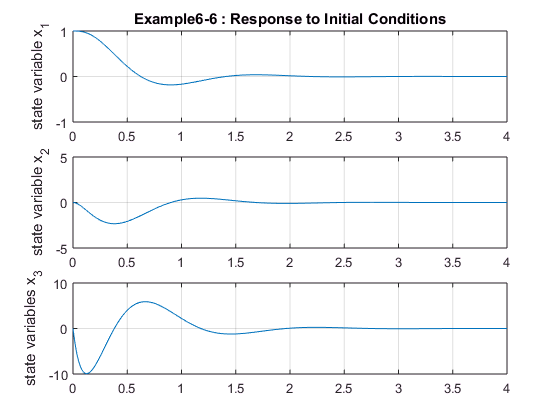

clear all; clc
% Define the system dynamics
A = [0 1 0; 0 0 1; -1 -5 -6];
B = [0; 0; 1];
K = [199 55 8];

% Define state-space equations for the system 
sys = ss(A-B*K, eye(3), eye(3), eye(3));

% Response to initial conditions
t = 0:0.01:4;
x = initial(sys, [1; 0; 0], t);
x1 = [1 0 0]*x';
x2 = [0 1 0]*x';
x3 = [0 0 1]*x';

%Plot 
subplot(311); plot(t, x1), grid
title('Example6-6 : Response to Initial Conditions')
ylabel('state variable x_1')
subplot(312); plot(t, x2), grid
ylabel('state variable x_2')
subplot(313); plot(t, x3), grid
ylabel('state variables x_3')